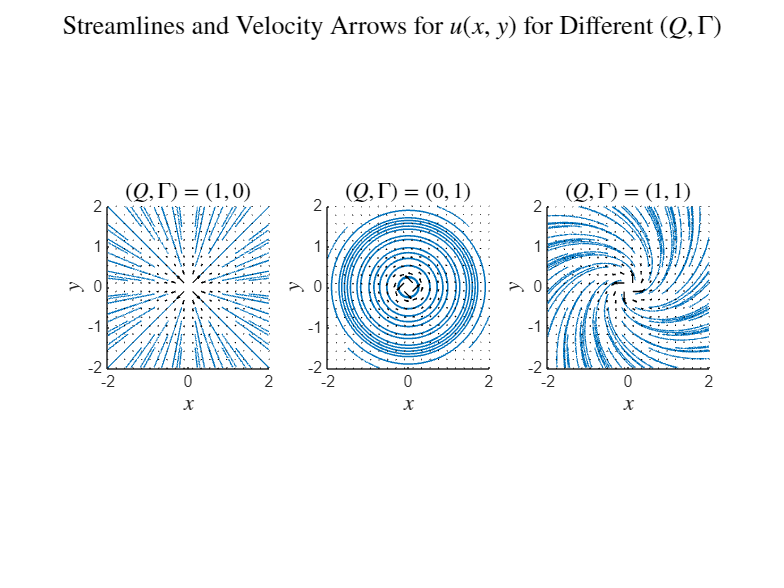

% Part (f): Plotting Velocity Component u(x,y) for Different (Q, Gamma) Pairs

% Clear workspace and close all figures
clear; close all; clc;

% Define the range for x and y
x = linspace(-2, 2, 400);
y = linspace(-2, 2, 400);
[X, Y] = meshgrid(x, y);

% Compute the denominator (x^2 + y^2)
denominator = X.^2 + Y.^2;

% Avoid division by zero by setting a minimum value
epsilon = 1e-6;
denominator(denominator < epsilon) = epsilon;

% Define the (Q, Gamma) pairs
cases = {
    struct('Q', 1, 'Gamma', 0, 'Title', '$(Q, \Gamma) = (1, 0) $'),
    struct('Q', 0, 'Gamma', 1, 'Title', '$(Q, \Gamma) = (0, 1) $'),
    struct('Q', 1, 'Gamma', 1, 'Title', '$(Q, \Gamma) = (1, 1) $')
};

% Initialize figure
figure;

% Loop through each case and plot u(x,y)
for i = 1:length(cases)
    Q = cases{i}.Q;
    Gamma = cases{i}.Gamma;
    titleStr = cases{i}.Title;
    
    % Compute u(x,y) based on the given (Q, Gamma)
    U = (Q .* X - Gamma .* Y) ./ (2*pi .* denominator);
    V = (Q .* Y + Gamma .* X) ./ (2*pi .* denominator); % Compute v(x,y) for streamlines
    
    % Plot using streamline for better visualization
    subplot(1, 3, i); % Create a subplot for each case
    hold on;
    
    % Create a grid of starting points for streamlines
    [startX, startY] = meshgrid(linspace(-1.5, 1.5, 10), linspace(-1.5, 1.5, 10));
    streamline(X, Y, U, V, startX, startY); % Plot streamlines
    
    % Add arrows to represent the velocity field
    % Use a coarser grid for arrows to avoid clutter
    [Xq, Yq] = meshgrid(linspace(-2, 2, 20), linspace(-2, 2, 20)); % Coarser grid for arrows
    Uq = (Q .* Xq - Gamma .* Yq) ./ (2*pi .* (Xq.^2 + Yq.^2));
    Vq = (Q .* Yq + Gamma .* Xq) ./ (2*pi .* (Xq.^2 + Yq.^2));
    quiver(Xq, Yq, Uq, Vq, 'k'); % Plot arrows in black
    
    title(titleStr, 'Interpreter', 'latex', 'FontSize', 12);
    xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 12);
    axis equal tight; % Equal scaling for x and y axes
    set(gca, 'Color', 'w'); % Set axes background color to white
    set(gcf, 'Color', 'w'); % Set figure background color to white
end

% Enhance layout
sgtitle('Streamlines and Velocity Arrows for $u(x, y)$ for Different $(Q, \Gamma)$', 'Interpreter', 'latex', 'FontSize', 14);